### **Resolução de Sistemas de Lineares de igualdade**

### **Eliminação Gaussiana**

**Algoritmo:**

Dada a matriz quadrada $A$de ordem $n$ e o vetor de recurso $b$

#### Para $k$ de 1 até $n-1$

####         Para  $i$ de $k+1$ até $n$

####             
$$m=a_{ij}/a_{ik}$$


####             
$$a_{ik}=0$$


####             Para $j$ de $k+1$ até $n$

####                 
$$a_{ij}= a_{ij}-ma_{kj}$$


####             Fim

####             
$$b_{i} = b_{i} - mb_{k}$$


####         Fim

#### Fim

**Implementação:**

A=[3 2 4;1 1 2;4 3 -2];
b=[1;2;3];
%[l,c] = size(A);
n = length(b);
for k = 1:n-1
    for i=(k+1):n
        m=A(i,k)/A(k,k);
        A(i,k) = 0;
        for j = (k+1):n
            A(i,j)=A(i,j) - m*A(k,j);
        end
        b(i)=b(i)-m*b(k);
    end
end
A,b

A =    3.000000000000000   2.000000000000000   4.000000000000000
                   0   0.333333333333333   0.666666666666667
                   0                   0  -8.000000000000000


b =    1.000000000000000
   1.666666666666667
  -0.000000000000000


### **Resolução de sistema com matriz triangular superior**

**Algoritmo:**

Dada a matriz triangular superior$A$de ordem $n$ e o vetor de recurso $b$

### 
$$x_{n}=\frac{b_{n}}{a_{nn}}$$


### Para $k$ de $n-1$até $1$

###         
$$s = 0$$


###         Para  $j$ de $k+1$ até $n$

###                 
$$s = s + a_{kj}x_{j}$$


###                 
$$x_{k} = \frac{b_{k} - s}{a_{kk}}$$


###           Fim

### Fim

**Implementação:**

x(n) = b(n)/A(n,n);
for k= (n-1): -1:1
    s=0;
    for j=(k+1):n
        s=s+A(k,j)*x(j)
        x(k)=(b(k)-s)/A(k,k);
    end
end

$$s = \frac{1}{27021597764222976}$$

$$s = \frac{45035996273704959}{4503599627370496}$$

$$s = 10$$

x

$$x = \left(\begin{array}{ccc} -3 & \frac{45035996273704959}{9007199254740992} & \frac{1}{18014398509481984} \end{array}\right)$$

**Exercício:** Resolva o sistema linear, a seguir, utilizando os algoritmos da Eliminação de Gauss e da resolução de sistema triangular superior.

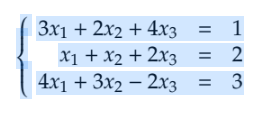

% Definir a matriz de coeficientes e o vetor de termos independentes
A = [3, 2, 4;
     1, 1, 2;
     4, 3, -2];
b = [1; 2; 3];

% Construir a matriz aumentada
Ab = [A, b];
n = size(Ab, 1);

% Eliminação de Gauss
for k = 1:n-1
    % Verificar se o pivô é zero
    if abs(Ab(k, k)) < 1e-10
        error('Matriz singular ou pivô nulo.');
    end
    
    % Eliminação das variáveis abaixo do pivô
    for i = k+1:n
        m = Ab(i, k) / Ab(k, k);
        Ab(i, k:end) = Ab(i, k:end) - m * Ab(k, k:end);
    end
end

% Substituição Regressiva
x = zeros(n, 1);
for i = n:-1:1
    x(i) = (Ab(i, end) - Ab(i, i+1:n) * x(i+1:n)) / Ab(i, i);
end

% Exibir resultados
fprintf('Solução:\n');

Solução:


fprintf('x1 = %.4f\n', x(1));

x1 = -3.0000


fprintf('x2 = %.4f\n', x(2));

x2 = 5.0000


fprintf('x3 = %.4f\n', x(3));

x3 = 0.0000
